% I hate warnings 
warning off; 

% Create a DEM of some size 
sizeDEM = 40;
ZI = peaks(sizeDEM);

% Assert DEM
figure; clf; hold off; 
tic;
surf(ZI);
toc;

Elapsed time is 0.008598 seconds.


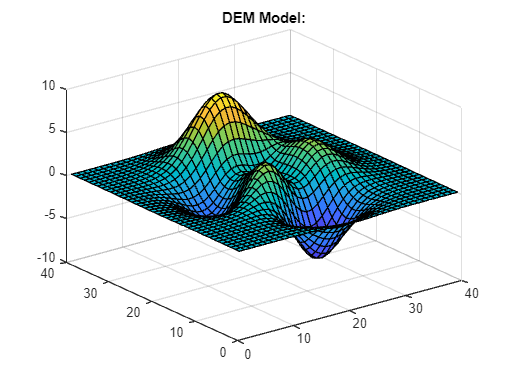

title('DEM Model:');

disp('-----');

-----


TIN with Tol = 0.1


Elapsed time is 0.016616 seconds.


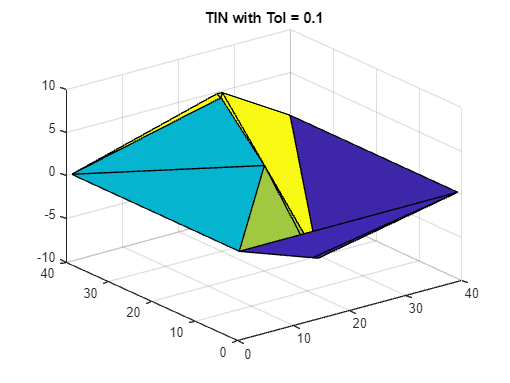

-----


TIN with Tol = 0.01


Elapsed time is 0.016704 seconds.


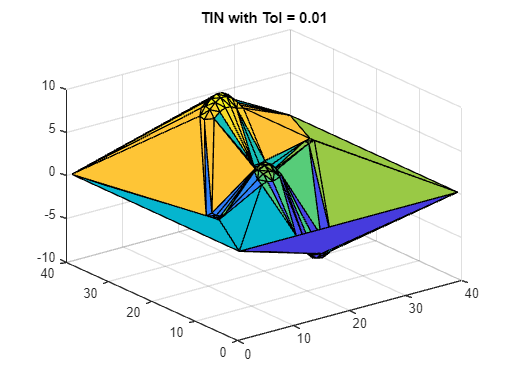

-----


TIN with Tol = 0.001


Elapsed time is 0.019728 seconds.


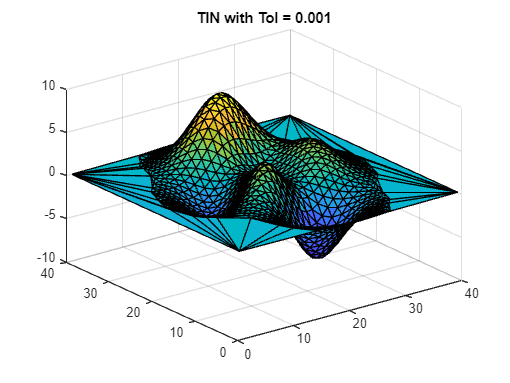

-----



% Create TINs of Different Tolerances
for i = 1:3

    % Iteratively Set Tolerance
    tol = 1*10^(-i);
    name = append('TIN with Tol = ', num2str(tol));
    disp(name);

    % Create Figure
    figure; clf; 

    % Find TIN model from DEM shown above
    [tri, x, y, z] = myTIN(ZI, tol);

    % Plot the TIN found 
    tic;
    trisurf(tri, x, y, z);
    toc;
    
    % Update Figure and Separate
    title(name);
    disp('-----');

end

## Condensed Function for TINtools: 

function [tri, x, y, z, ZIe, ZIn] = myTIN(myDEM, tol)
% Uses a Digital Elevation Model (DEM) to develop a Triangular Irregular Network (TIN)


% Create a referencing matrix

R = [0, 1; 1, 0; 0, 0];

% Select VIP points

ZImask = vipmask(myDEM,1/tol,true);

% Create the TIN from the image, refmat, and mask

[tri, x, y, z] = dem2tin(myDEM,R,ZImask);

% Check error

[ZIe, ZIn] = verifytin(myDEM,R,x,y,z);
end